# Lab: Monte Carlo Localisation

In the following, you are supposed to replace the amcl localization in the navigation stack with a Matlab code. This requires to launch the Gazebo simulator and Rviz with amcl localization and robot navigation turned off.

For this, move the files ${\tt house.yaml}$ and ${\tt house.pgm} $in the ${\tt maps} $folder of the ${\tt turtlebot3\_navigation}$ package. To locate this package, use the command

in a terminal which will return you the corresponding path. If admin rights are required to copy files into the ${\tt maps}$ folder you can use the command 

Then, to achieve the whole configuration of deactivated Monte Carlo localization and navigation stack, save the launch file ${\tt turtlebot3\_noamcl.launch}$ to the ${\tt launch}$ folder of the ${\tt turtlebot3\_navigation}$ package. Again if admin rights are required, you can use

In two separate terminals start Gazebo and Rviz with commands:

1) Compared to the real robots, the odometry data in the Gazebo simulator contain a lower noise level. To make the simulation more realistic, the helper function ${\tt GazeboNoisyOdom}$ is provided in the template which adds additional noise to the received odometry data. Review the ${\tt GazeboNoisyOdom}$ helper function.

2) The helper class ${\tt AMCLWandererRST.m}$ drives the robot around randomly while avoiding obstacles with VFH+. Copy it to your Matlab working directory. Use the template for the following tasks for the implementation of the AMCL algorithm.

close all; clear all; clc;
% Init ROS
rosshutdown;
rosinit('http://ubuntu:11311/');

Initializing global node /matlab_global_node_32413 with NodeURI http://192.168.2.111:49714/


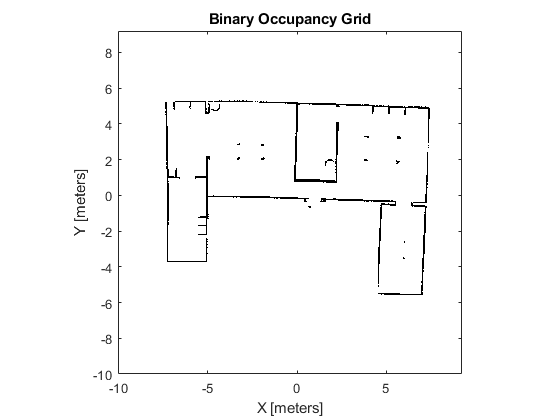

%% Load map
mapimage = ~logical(imread('house.pgm'));   % resolution 0.05 m/pixel
map = robotics.BinaryOccupancyGrid(mapimage(:,:,1),20);
map.GridLocationInWorld = [-10 -10];
figure(1);
show(map);

%% Create publisher and subscriber
% Create ROS subscribers for retrieving sensor and odometry measurements from TurtleBot.
laserSub = rossubscriber('/scan');
scanMsg = receive(laserSub);
odomSub = rossubscriber('/odom');

% Query the Transformation Tree (tf tree) in ROS.
tftree = rostf;

3) Set up the turtlebot motion model (${\tt robotics.OdometryMotionModel}$): The TurtleBot motion is estimated from odometry data. The ${\tt Noise}$ attribute reflects the uncertainty in the robot's angular and linear movement. Initialize the motion model where all noise parameters $$\alpha_i$$ should be initialized with $$0.05$$.

odometryModel = odometryMotionModel;
odometryModel.Noise = [0.05 0.05 0.05 0.05];

% Task 11
% odometryModel.Noise = [1.0 1.0 1.0 1.0];

4) Set up the turtlebot sensor model (${\tt robotics.LikelihoodFieldSensorModel}$): The likelihood field method computes the probability of perceiving a set of measurements by comparing the endpoints of the range finder measurements to the occupancy map. If the end points match the occupied points in occupancy map, the probability of perceiving such a measurement is high. Initialize the sensor model with for the house map, configure the following parameters:

- ${\tt SensorLimits}$ - Minimum and maximum range of sensor (defined in $\texttt{scanMsg}$)

- ${\tt NumBeams}$- Number of beams used for likelihood computation (defined in $\texttt{scanMsg}$)

- ${\tt Map}$ - The $\texttt{BinaryOccupancyGrid}$ of the map

- ${\tt MeasurementNoise}$ - Standard deviation of measurement noise (a reasonable value is 0.1)

- ${\tt RandomMeasurementWeight}$ - Weight $$\alpha_{rnd}$$ for the probability of random measurement $$p_{rnd}$$ (a reasonable value is 0.05)

- ${\tt ExpectedMeasurementWeight}$ - Weight $$\alpha_{hit}$$ for the probability of expected measurement $$p_{hit}$$ (a reasonable value is 0.95).

sensorModel = likelihoodFieldSensorModel;
sensorModel.SensorLimits = [double(scanMsg.RangeMin) double(scanMsg.RangeMax)];
sensorModel.NumBeams = size(scanMsg.Ranges, 1);
sensorModel.Map = map;
sensorModel.MeasurementNoise = 0.1;
sensorModel.RandomMeasurementWeight = 0.05;
sensorModel.ExpectedMeasurementWeight = 0.95;

% Task 11
% sensorModel.RandomMeasurementWeight = 1.0;
% sensorModel.ExpectedMeasurementWeight = 0.0;


5) The attribute ${\tt SensorPose}$ of the ${\tt robotics.LikelihoodFieldSensorModel}$ refers to the pose of the range sensor relative to the robot. Set ${\tt SensorPose}$ to the coordinate transform of the sensor with respect to the robot base (${\tt /base\_link}$). The transform can be obtained from the ROS transformation tree using$ {\tt getTransform}$ by identifying the frame of ${\tt scanMsg}$. Note, that the transform needs to be specified as a three-element vector, i.e. a 2D pose.

sourceFrame = '/base_link';
targetFrame = scanMsg.Header.FrameId;
waitForTransform(tftree, sourceFrame, targetFrame);
sensorTransform = getTransform(tftree, sourceFrame, targetFrame);

laserQuat = [sensorTransform.Transform.Rotation.W ...
             sensorTransform.Transform.Rotation.X ...
             sensorTransform.Transform.Rotation.Y ...
             sensorTransform.Transform.Rotation.Z];
laserRotation = quat2eul(laserQuat, 'ZYX');

sensorModel.SensorPose = [sensorTransform.Transform.Translation.X ...
                          sensorTransform.Transform.Translation.Y laserRotation(1)];

6) Set up an AMCL object ${\tt amcl}$ with ${\tt robotics.MonteCarloLocalization}$ and assign the$ {\tt MotionModel}$ and $
   	{\tt SensorModel} $ properties in the ${\tt amcl}$ object. 

amcl = monteCarloLocalization;
amcl.MotionModel = odometryModel;
amcl.SensorModel = sensorModel;

7) Configure the ${\tt amcl}$ object for localization with initial pose estimate and provide the following properties

amcl.UpdateThresholds = [0.2, 0.2, 0.1];
amcl.ResamplingInterval = 1;
amcl.UseLidarScan = true;
amcl.ParticleLimits = [200 2000];
amcl.GlobalLocalization = false;  
amcl.InitialPose = AMCLGazeboTruePose; % Get true initial pose
amcl.InitialCovariance = 0.2*eye(3);

% Task 13
% amcl.ParticleLimits = [2000 10000];
% amcl.GlobalLocalization = true;

The helper function ${\tt AMCLGazeboTruePose}$ queries the true pose from the Gazebo simulator.

8) A helper class $\texttt{AMCLVisualization}$ is provided for visualization and driving the TurtleBot. Set up a helper object which can be obtained from the $\texttt{AMCLVisualization}$ function to plot the map and update the robot's estimated pose (green), particles (blue), and laser scan (red) on the map. The class constructor takes as an input the $\texttt{BinaryOccupancyGrid} $of the map.

visualizationHelper = AMCLVisualization(map);

9) Within a ${\tt while}$ loop 

- messages arriving on the ${\tt scan}$ topic are received and converted to a $\texttt{lidarScan}$ object

- the latest odometry information from  the ${\tt odom}$ topic is received and converted to a ${\tt pose}$ vector regarding $$x_t,y_t,\theta_t$$, e.g. with the helper function ${\tt OdometryMsg2Pose}$.

- update the estimated robot's pose and covariance based on the current odometry and laser $\texttt{scan}$ object

- Each time the AMCL updates the set of particles, visualize the robot's estimated pose, particles and laser scans on the map

If Matlab is not responding anymore or you experience the Matlab error ${\tt Connection \; to \; process \; with \; Exchange: \; ... \; was \; lost.}$, restart Matlab. Try to avoid scrolling within the Matlab Live-Script when the localization is running as it may lead to a crash of Matlab as well.

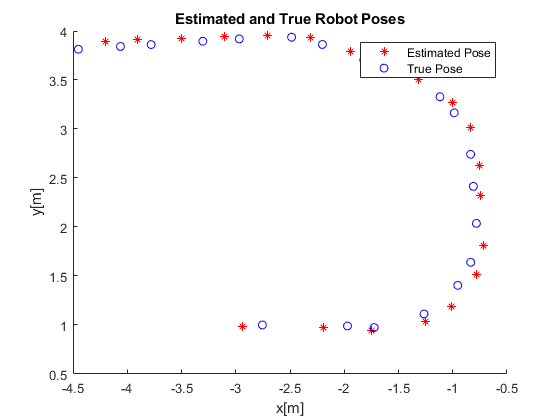

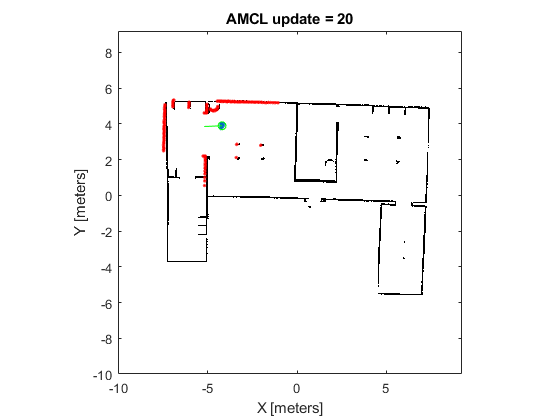

% Create ROS publisher for sending out velocity commands to TurtleBot. TurtleBot subscribes to '/mobile_base/commands/velocity' for velocity commands.
[velPub,velMsg] = rospublisher('/cmd_vel','geometry_msgs/Twist'); % /mobile_base/commands/velocity

%% Set up movement controller
% Robot motion is essential for the AMCL algorithm. 
% Drive TurtleBot randomly using the ExampleHelperAMCLWanderer class, which drives the robot inside the environment while avoiding obstacles using the robotics.VectorFieldHistogram class.
wanderHelper = AMCLWandererRST(sensorTransform, velPub, velMsg);
laserSub.NewMessageFcn = @wanderHelper.scan_callback;

%% Localization procedure
numUpdates = 20;

oldTruePose = AMCLGazeboTruePose();
iUpdate = 1;
rate = 0.25; % Rate of 0.5 Hz
rateObj=robotics.Rate(rate); 
rateObj.reset;  % reset time at the beginning of the loop

figure_true_vs_estimation = figure;
figure_particles = figure;

while iUpdate <= numUpdates
    laserMsg = receive(laserSub);
    
    odomMsg = odomSub.LatestMessage;
    [x, y, theta] = OdometryMsg2Pose(odomMsg);
    odomPose = [x, y, theta];
    
    % Task 12
    % odomPose = GazeboNoisyOdom();
    
    scan = lidarScan(laserMsg);
    
    [isUpdated, estimatedPose, estimatedCovariance] = amcl(odomPose, scan);
    
    % Task 15
    [particles, weights] = amcl.getParticles();
    
    % Task 16
%     figure(figure_particles)
%     plot3(particles, particles(:,2), particles(:,3), 'r+')
%     title('Particle Cloud and Nearest Neighbours')
%     xlabel('x')
%     ylabel('y')
%     zlabel('Theta')  
    
%     Task 17
    kdtree_searcher = KDTreeSearcher(particles);
    
%     Task 18
%     K = 500;
%     xx = [2 2 0];
%     [idx, dist] = knnsearch(kdtree_searcher, xx, 'K', K);
%     figure(figure_particles)
%     clf;
%     plot3(particles, particles(:,2), particles(:,3), 'r+')
%     hold on; 
%     plot3(particles(idx,:), particles(idx,2), particles(idx,3), 'bo')
%     title('Particle Cloud and Nearest Neighbours')
%     xlabel('x')
%     ylabel('y')
%     zlabel('Theta') 
     
    if isUpdated        
        % Plots
        plotStep(visualizationHelper, amcl, estimatedPose, scan, iUpdate)
      
        truePose = AMCLGazeboTruePose();
        figure(figure_true_vs_estimation)
        hold on;
        plot(estimatedPose(1), estimatedPose(2), 'r*', truePose(1), truePose(2), 'bo')
        title('Estimated and True Robot Poses')
        legend('Estimated Pose', 'True Pose')
        xlabel('x[m]')
        ylabel('y[m]')
        
        iUpdate = iUpdate + 1;
    end
    
    % Drive reverse when robot gets stuck in Gazebo
    newTruePose = AMCLGazeboTruePose();
    if (sqrt((newTruePose(1) - oldTruePose(1))^2 + (newTruePose(2) - oldTruePose(2))^2) < 0.001)
        laserSub.NewMessageFcn = [];
        t_start_reverse = rateObj.TotalElapsedTime;
        while (rateObj.TotalElapsedTime - t_start_reverse < 3.0)
            velMsg.Linear.X = -0.5;
            send(velPub, velMsg);
            waitfor(rateObj);
        end
        laserSub.NewMessageFcn = @wanderHelper.scan_callback;
    end
    oldTruePose = newTruePose;
    
    % Task 14 
%     if iUpdate == floor(0.5 * numUpdates)
%         laserSub.NewMessageFcn = [];
%         t_start_reverse = rateObj.TotalElapsedTime;
%         disp('Displace robot in the Gazebo simulation...')
%         
%         while (rateObj.TotalElapsedTime - t_start_reverse < 30.0) 
%             stop(wanderHelper);
%             waitfor(rateObj);
%         end
%         laserSub.NewMessageFcn = @wanderHelper.scan_callback;
%     end
    
    waitfor(rateObj);
end

% Stop Wanderer
stop(wanderHelper);
laserSub.NewMessageFcn = [];
%rosshutdown

10) The true pose can be obtained from the ${\tt AMCLGazeboTruePose}$ function at each update of the AMCL algorithm. Plot the evolution of the true and estimated pose in a separate figure.

11) Investigate the evolution of particles according to the motion model only. For that purpose set

which ignores the range information as all readings become equally likely. Initialize the pose at the true robots pose with zero covariance and observe the spread of the point cloud. To accentuate the particle spread, increase the noise in the motion model.

Reset the parameters to their original values afterwards.

12) Analyze the performance of the ${\tt amcl}$ localization when using the noisy odometry poses from ${\tt GazeboNoisyOdom()}$ instead of the original odometry poses which were obtained directly from the ${\tt odom}$ topic.

13) Reconfigure your AMCL algorithm for global localization. For that purpose, set the $\texttt{amcl}$ property ${\tt GlobalLocalization}$ to ${\tt true}$ in which case the particles are uniformly distributed across the entire map. Hence, global localization requires a large number of particles. Increase the lower and upper bounds on the number of particles ${\tt ParticleLimits}$ in the ${\tt acml} $object. Test the ability of the algorithm to estimate the true pose by global localization.

14) (Optional) Test the ability of the AMCL algorithm to recover from the kidnapped robot problem. While the Gazebo simulator is running, displace the robot in the simulator and observe whether the ACML algorithms recovers from the kidnapping. For this, make the robot stop after half of the update iterations within the while loop using

When the robot stops, you have $$30\,\mathrm{s}$$ time to displace the robot in Gazebo. For this, select the tab $\textit{World}$ -> $\textit{Models}$ -> $\textit{turtlebot3}$ (the last). This should select the robot visualized by a white bounding box around the robot in Gazebo. Now, press "T" on the keyboard which enables the translation mode and drag-and-drop the robot to a different place. Press "Esc" to leave the translation mode afterwards. Now, wait until the localization procedure continues.

15) Retrieve the particles generated at each iteration of your AMCL algorithm for global localization with

which returns the current particles of the MonteCarloLocalization object. Notice that the number of rows can change with each iteration of the MCL algorithm.

16) Plot the particle poses over the course of AMCL iterations in a separate 3D plot (${\tt plot3}$).

17) Build a k-d tree for the particle set at each iteration step of the particle filter with ${\tt KDTreeSearcher}$.

18) Search the k-d tree for the $$K=500$$ nearest neighbors of the pose $$x=[2 \ 2 \ 0]$$ with ${\tt knnsearch(kdtree, x, 'K', K)}$. Overlay the original particle plot with the plot of	the nearest neighbours in a different colour.

19) (Optional) ${\tt knnsearch}$ not only provides the index to the $$K$$ nearest neighbours but also the mutual distance to the query point. Calculate the continuous probability density of the particle sets at each iteration for a grid that spans the volume $$x \in [-5, \ 15 ]$, $x \in [-10, \ 10]$$ and $$ \theta \in [-\pi, \ \pi ]$$. For this, use the kernel density estimation from the subset of nearest nearest neighbours. Use a Gaussian kernel with $ $h=1$$. Visualize the probability density together with the particles in a contour slice plot (${\tt contourslice} $). Initially, set up the grid using

For plotting the estimated kernel density use

## Maximum Likelihood Estimate of Sensor Model Parameters

20) The file ${\tt sensordata.mat}$ contains sensor range readings ${\tt sensordata(:,1)}$ and the corresponding expected reading from ray tracing (clipped at maximum range reading) ${\tt sensordata(:,2)}$. Plot the histogram of true range readings $$z_i$$ with ${\tt histogram}$. Use the command ${\tt yyaxis \; left}$ before plotting to plot the histogram w.r.t. the left y-axis. The overall readings originate from a sensor range $$z_i \in [0.0, 2.0]$$.

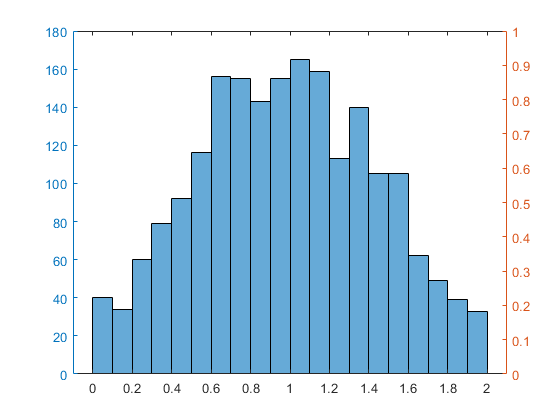

clear;
close all;
load('sensordata.mat');
z = sensordata(:, 1);
zexp = sensordata(:, 2);

yyaxis left
histogram(z)

21) Implement a function

that computes the likelihood of a range reading ${\tt z}$, for an expected reading$ {\tt zexp}$ and sensor model parameters $$\beta=[\alpha_{hit}, \alpha_{random}, \sigma_{hit}]$$ according to the simplified version ignoring $$p_{unexp},p_{max}$$.

The probabilities $$p_{hit}$$ and $$p_{rand}$$ for each sensor reading are calculated from the actual sensor readings $\texttt{z(k)}$ and the expected sensor readings $\texttt{zexp(k)}$ with the Matlab function $\texttt{pdf}$:

returns the two-parameter distribution family specified by the string ${\tt name}$, evaluated at the values in ${\tt x}$. ${\tt A} $ and ${\tt B}$ denote the parameters for the distribution, typically ${\tt A}$ denotes the mean and ${\tt B}$ the variance. Use the following code as a template for implementing the function:

The input and output arguments ${\tt p, z, zexp}$ are supposed to be vectors (arrays) of data not merely scalars, ${\tt beta}$ contains the parameter vector.

22) Implement a function

that calculates the log likelihood of the entire data vector ${\tt z, zexp}$ given the parameter vector ${\tt beta}$. Compute the log-likelihood of the entire probability vector $\texttt{p}$ for a parameter vector $$\beta=[0.6 \ 0.4 \ 0.5]$$ by summation of the logarithms of the probability vector $\texttt{p}$.

beta = [0.6 0.4 0.5];
loglikelihood = logpdata(z, zexp, beta);
assert(round(loglikelihood) == -1129);

23) Maximize the log likelihood of the data w.r.t. the parameter $$\beta=[\alpha_{hit}, \alpha_{random}, \sigma_{hit}]$$ subject to the constraint that $$\alpha_{hit}+\alpha_{random}=1.0$$. Use ${\tt fmincon}$ to find the parameter vector $$\beta^*$$ that maximizes the likelihood. The	first argument to ${\tt fmincon}$ is a function handle to your objective function, which is the negative of ${\tt logpdata}$ as you want to maximize the likelihood of the data (see Scientific Programming Optimization Toolbox).

lb = [0 0 0];
ub = [1 1 5];
A = [];
b = [];
Aeq = [1 1 0];
beq = 1;
betainit = [0.6 0.4 0.5];

optfun = @(beta) -logpdata(z, zexp, beta);

[betastar, fval] = fmincon(optfun, betainit, A, b, Aeq, beq, lb, ub);


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


assert(all(round(betastar, 4) == [0.7525, 0.2475, 0.2801]));

24) Plot the probability of the sensor model for $$z_{exp}=1.0$$ with the identified parameter vector $$\beta ^*$$ for the subset of range data  $$z_{exp} \in [0.95, 1.05]$$ into the same figure. Use the command ${\tt yyaxis \; right}$ before plotting since the probability has a different scale than the histogram.

25) (Optional) Maximize the log likelihood of the data w.r.t. the full parameter vector$$\beta=[\alpha_{hit}, \alpha_{random}, \alpha_{unexp}, \alpha_{max}, \sigma_{hit}, \lambda]$$ subject to the constraint that $$\alpha_{hit}+\alpha_{random}+\alpha_{unexp}+\alpha_{max}=1.0$$. Use an exponential function for modelling the probability of unknown sensor readings. For this, extend the likelihood function according to:

Use ${\tt fmincon}$ to find the new parameter vector $$\beta^*$$ that maximizes the argument. Therefore, extend $\texttt{lb, ub, Aeq}$ and $\texttt{betainit}$ according to

Plot the histogram of the sensor readings together with the probability of the new sensor model for $$z_{exp}=1.0$$ with the new identified parameter vector $$\beta^*$$. 

# Functions that have to be implemented

function p = pmeasurement_simplified(z, zexp, beta)
    
    sigmahit = beta(3);
    n=length(z);
    p=zeros(n, 1);
    out_of_range = 2.0;
    for k = 1:n
        if (z(k) < out_of_range)
           phit = pdf('Normal', z(k), zexp(k), sigmahit);   
        else
           phit = 0;
        end
        prand = pdf('Uniform', z(k), 0, out_of_range);  
         
        p(k) = beta(1)*phit + beta(2)*prand; 
    end
end
function p = pmeasurement(z, zexp, beta)
    
end

function loglikelihood = logpdata(z, zexp, beta)
    loglikelihood = 0;
    p = pmeasurement_simplified(z, zexp, beta);
    for k = 1:length(z)
        loglikelihood = loglikelihood + log(p(k)); 
    end
end

# Helper Functions

function noisyOdom = GazeboNoisyOdom()
    %ExampleHelperAMCLGazeboNoisyPose Returns the noisy odom output from Gazebo.
    
    % Obtain 'mobile_base' pose from Gazebo.
    odomSub = rossubscriber('/odom'); 
    gazeboPose = receive(odomSub);
    %.LatestMessage;
    % Compute [x,y,yaw] from stage pose data
    quat = [gazeboPose.Pose.Pose.Orientation.W, gazeboPose.Pose.Pose.Orientation.X, ...
        gazeboPose.Pose.Pose.Orientation.Y, gazeboPose.Pose.Pose.Orientation.Z];
    rot = quat2eul(quat);
    x = gazeboPose.Pose.Pose.Position.X;
    y = gazeboPose.Pose.Pose.Position.Y;
    yaw = rot(1);
    
    a1 = 0.005;
    a2 = 0.005;
    a3 = 0.005;
    a4 = 0.005;
    
    trans = sqrt(x*x + y*y);
    theta1 = 0;
    theta2 = yaw;
    rot1 = atan2(y, x) - theta1;
    rot2 = theta2-theta1-rot1;
    
    sd_rot1 = a1*abs(rot1) + a2*trans;
    sd_rot2 = a1*abs(rot2) + a2*trans;
    sd_trans = a3*trans + a4*(abs(rot1) + abs(rot2));
    
    trans =  trans + normrnd(0,sd_trans);
    rot1 = rot1 + normrnd(0, sd_rot1);
    rot2 = rot2 + normrnd(0, sd_rot2);
    
    x = trans*cos(theta1+rot1);
    y = trans*sin(theta1+rot1);
    yaw = theta1 + rot1 + rot2;
    noisyOdom = [x,y,yaw];
end

function groundTruthPose = AMCLGazeboTruePose()
    %ExampleHelperAMCLGazeboTruePose Returns the true robot pose from Gazebo.
    % This function subscribes to gazebo/model_states and find the
    % 'mobile_base' pose data. 
    
    % Copyright 2015 The MathWorks, Inc.
    
    % Obtain 'mobile_base' pose from gazebo.
    posesub = rossubscriber('gazebo/model_states');
    gazeboModelsPoses = receive(posesub);
    for i = 1:size(gazeboModelsPoses.Pose)
        if strcmp(gazeboModelsPoses.Name(i), 'mobile_base')
            break
        end
    end
    % Compute [x,y,yaw] from Gazebo pose data
    quat = [gazeboModelsPoses.Pose(i).Orientation.W, gazeboModelsPoses.Pose(i).Orientation.X, ...
        gazeboModelsPoses.Pose(i).Orientation.Y, gazeboModelsPoses.Pose(i).Orientation.Z];
    rot = quat2eul(quat);
    x = gazeboModelsPoses.Pose(i).Position.X;
    y = gazeboModelsPoses.Pose(i).Position.Y;
    yaw = rot(1);
    groundTruthPose = [x,y,yaw];
end

function [ x, y, theta ] = OdometryMsg2Pose( poseMsg )
    % convert odometry message to vector
    x=poseMsg.Pose.Pose.Position.X;
    y=poseMsg.Pose.Pose.Position.Y;
    eul=quat2eul([poseMsg.Pose.Pose.Orientation.W poseMsg.Pose.Pose.Orientation.X  poseMsg.Pose.Pose.Orientation.Y poseMsg.Pose.Pose.Orientation.Z]);
    theta=eul(1);
end